% read wav files
[audio_1,rate_1]=audioread("./src/myaudio/audio1.wav");
[audio_2,rate_2]=audioread("./src/myaudio/audio2.wav");
[audio_3,rate_3]=audioread("./src/myaudio/audio3.wav");
[audio_4,rate_4]=audioread("./src/myaudio/audio4.wav");

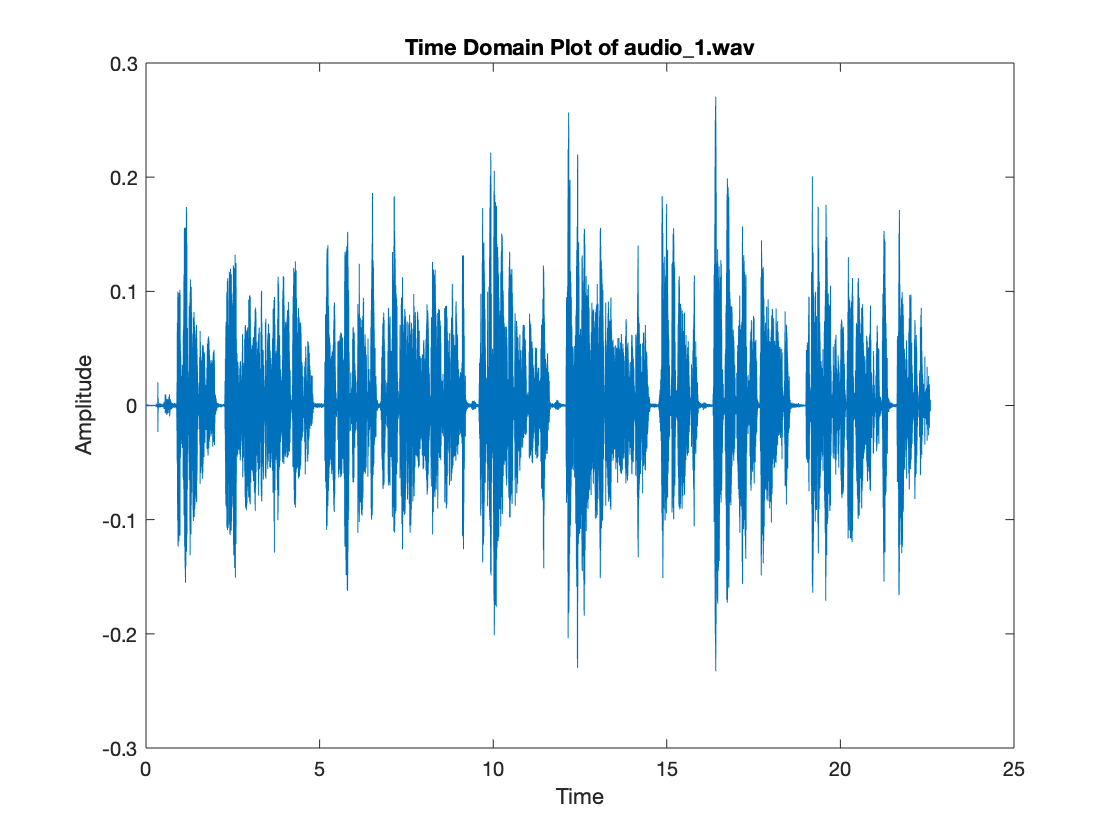

% time domain
% audio_1.wav
audio_vec=audio_1(:,1);
dt=1/rate_1;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_1.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_1.png');

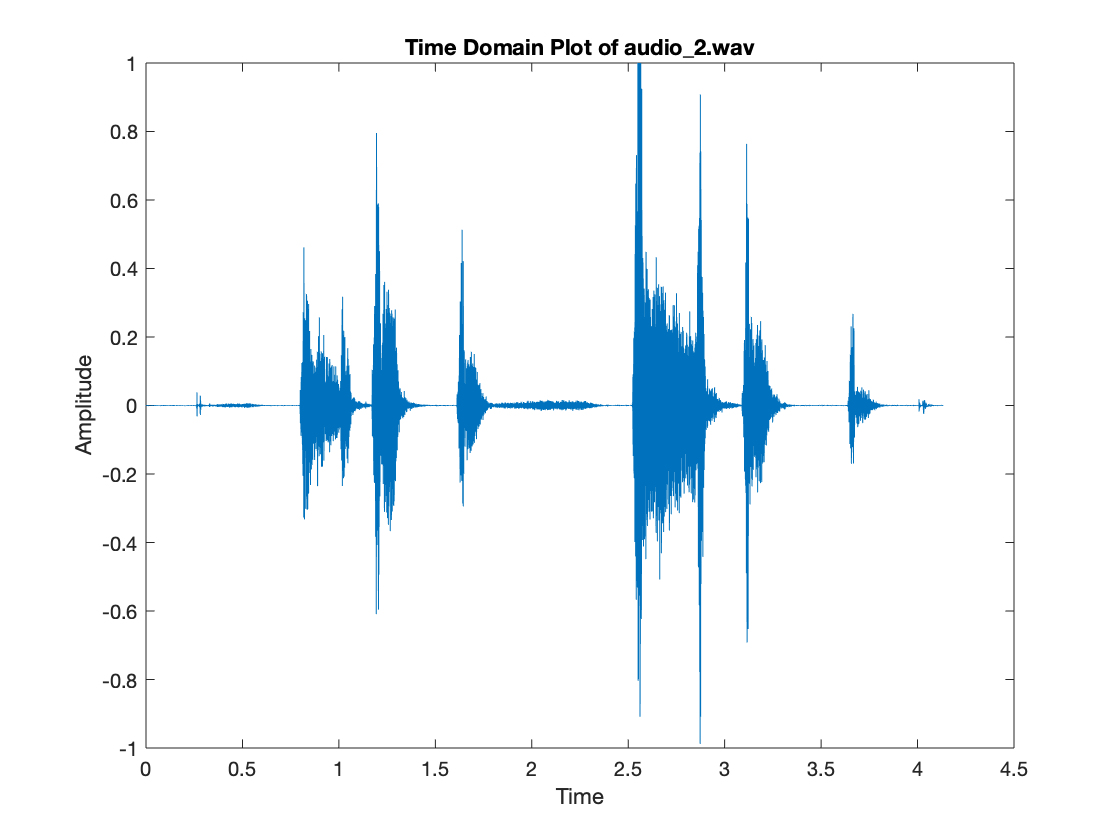

% audio_2.wav
audio_vec=audio_2(:,1);
dt=1/rate_2;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_2.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_2.png');

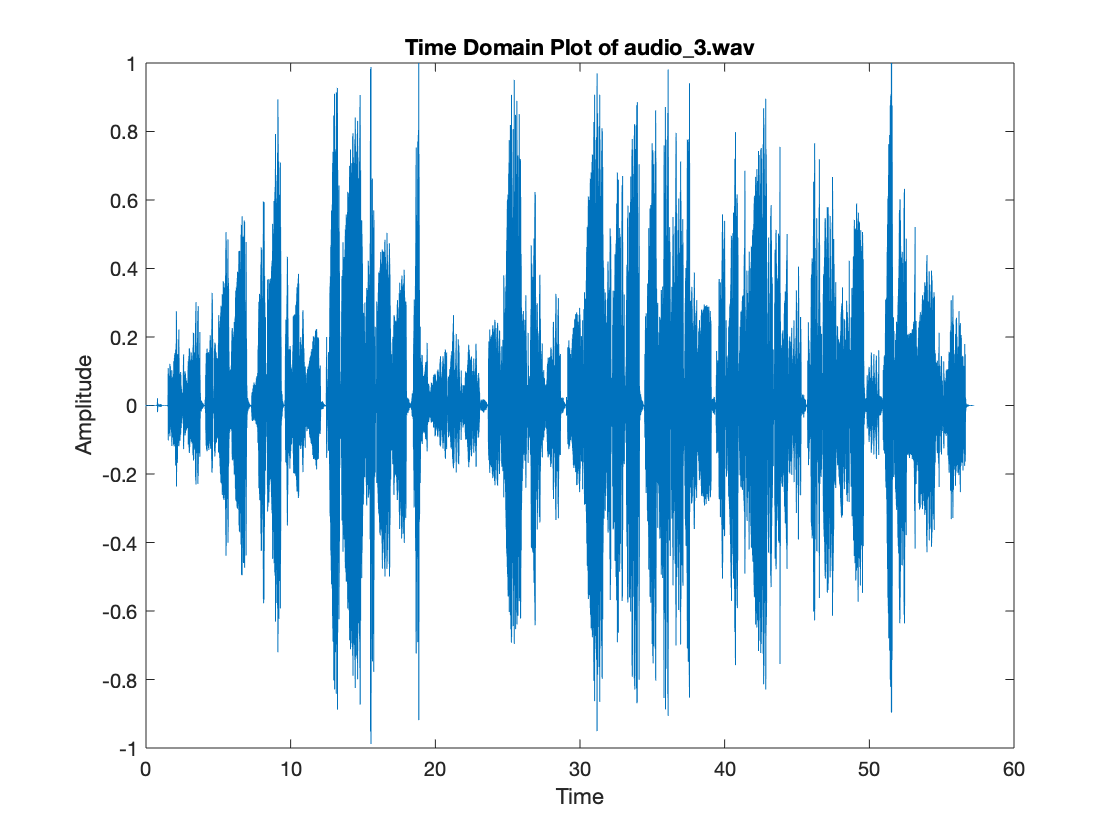

% audio_3.wav
audio_vec=audio_3(:,1);
dt=1/rate_3;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_3.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_3.png');

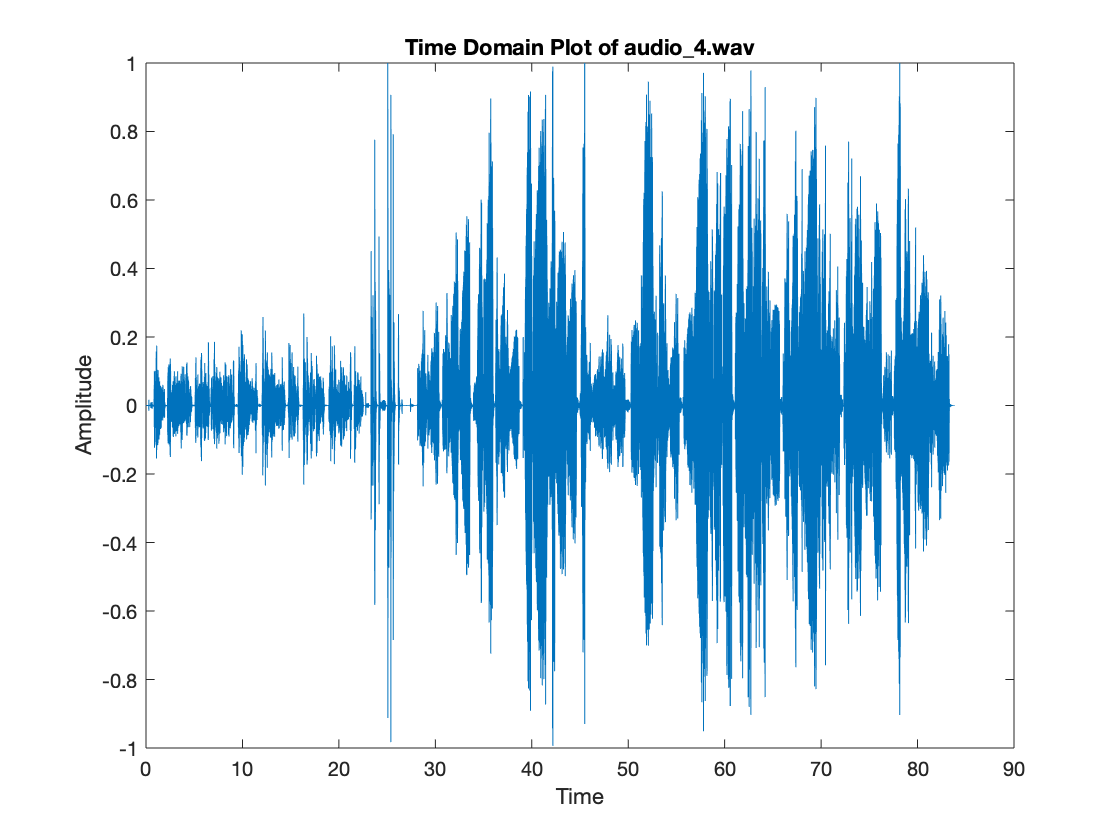

% audio_4.wav
audio_vec=audio_4(:,1);
dt=1/rate_4;
t=0:dt:(length(audio_vec)*dt)-dt;
fig=plot(t,audio_vec);
title('Time Domain Plot of audio\_4.wav');
xlabel('Time');
ylabel('Amplitude');
saveas(fig,'./result/time_domain/audio_4.png');

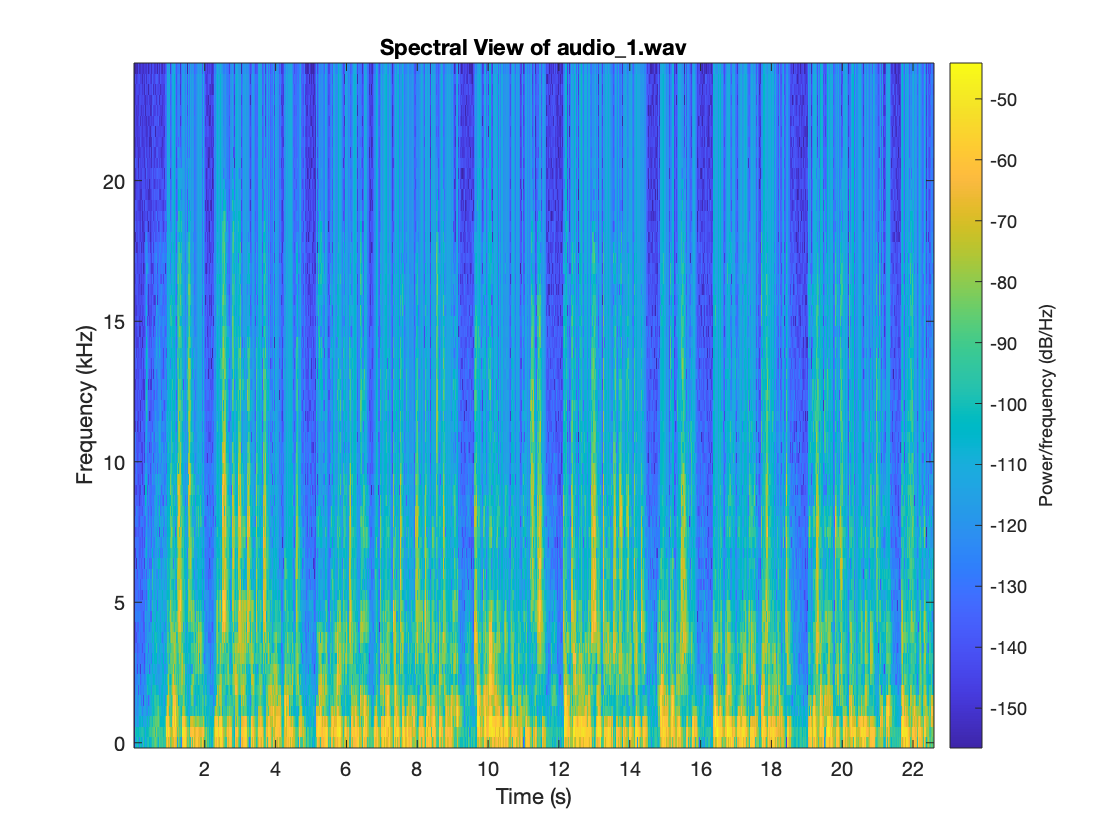

% spectral view
% audio_1.wav
audio_vec=audio_1(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_1,'yaxis');
title("Spectral View of audio\_1.wav");
saveas(gcf,'./result/spectral_view/audio_1.png');

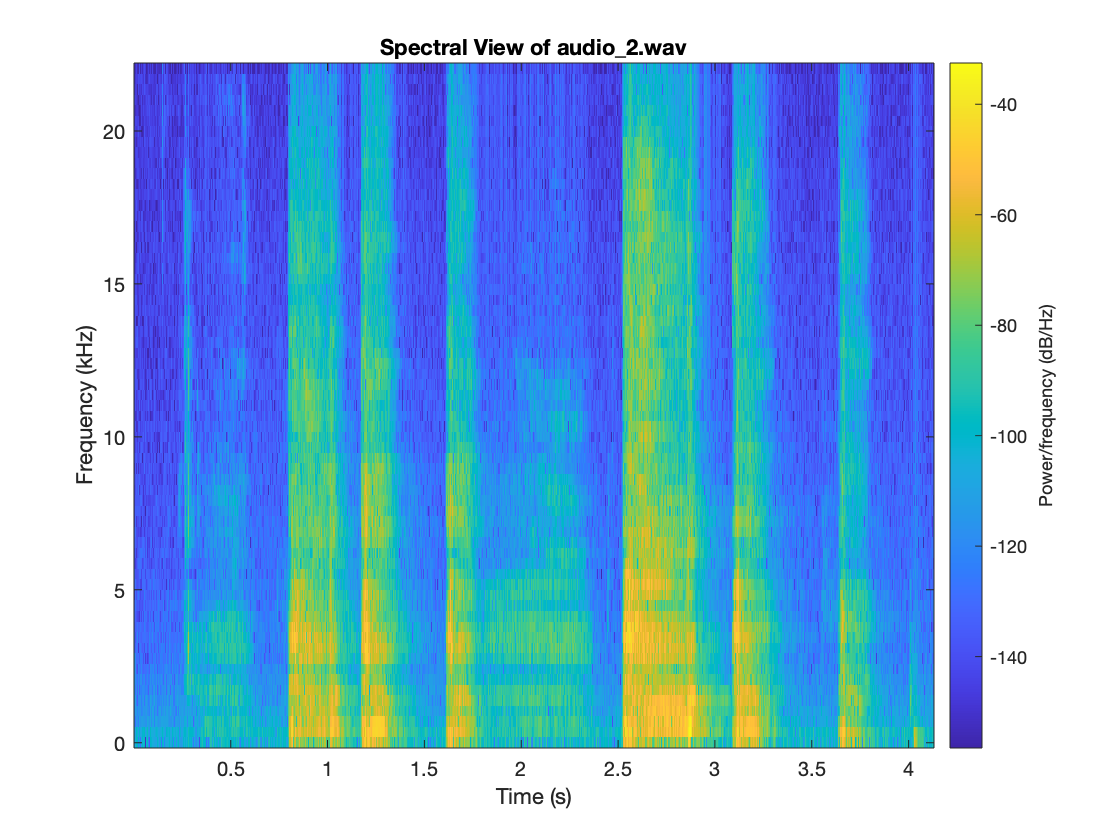

% audio_2.wav
audio_vec=audio_2(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_2,'yaxis');
title("Spectral View of audio\_2.wav");
saveas(gcf,'./result/spectral_view/audio_2.png');

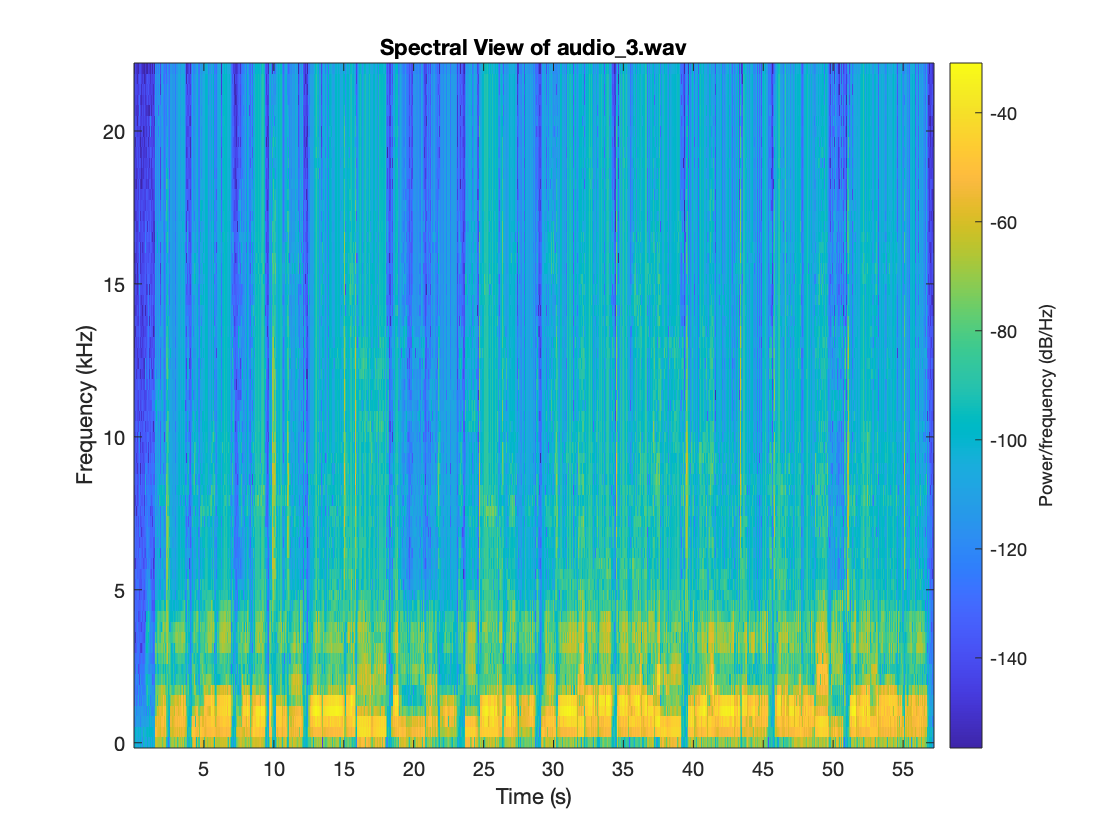

% audio_3.wav
audio_vec=audio_3(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_3,'yaxis');
title("Spectral View of audio\_3.wav");
saveas(gcf,'./result/spectral_view/audio_3.png');

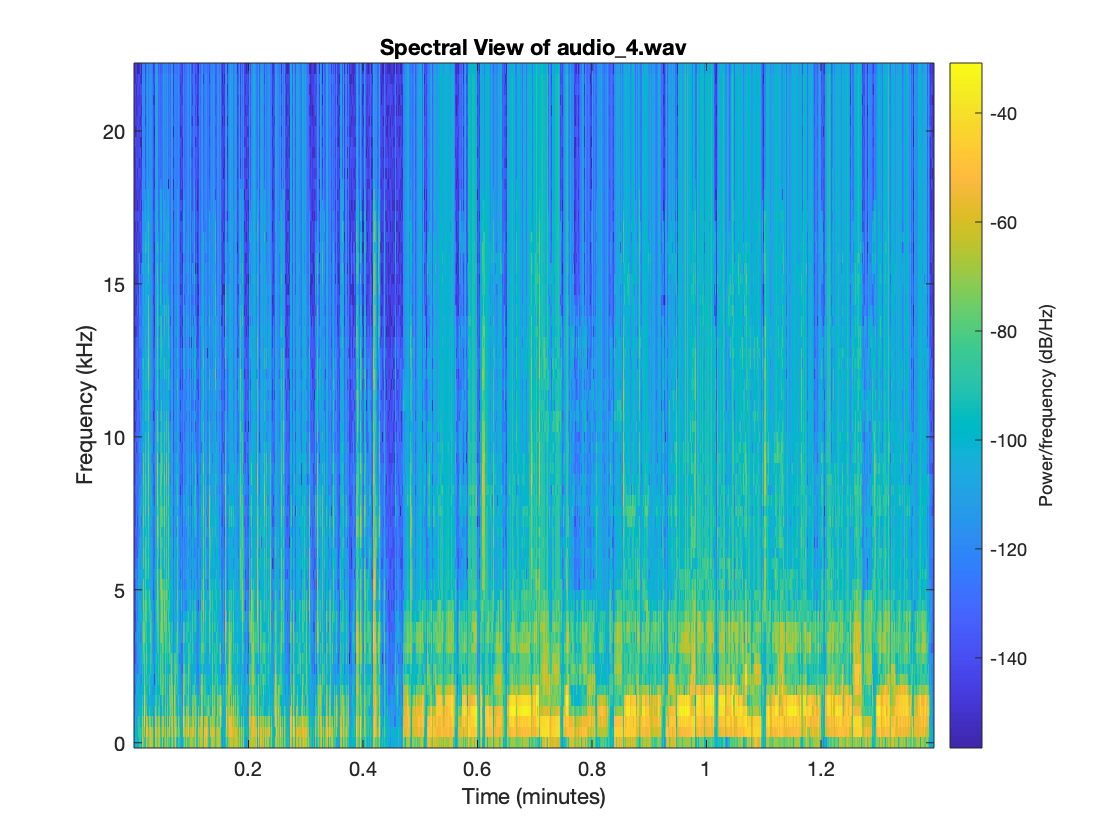

% audio_4.wav
audio_vec=audio_4(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_4,'yaxis');
title("Spectral View of audio\_4.wav");
saveas(gcf,'./result/spectral_view/audio_4.png');

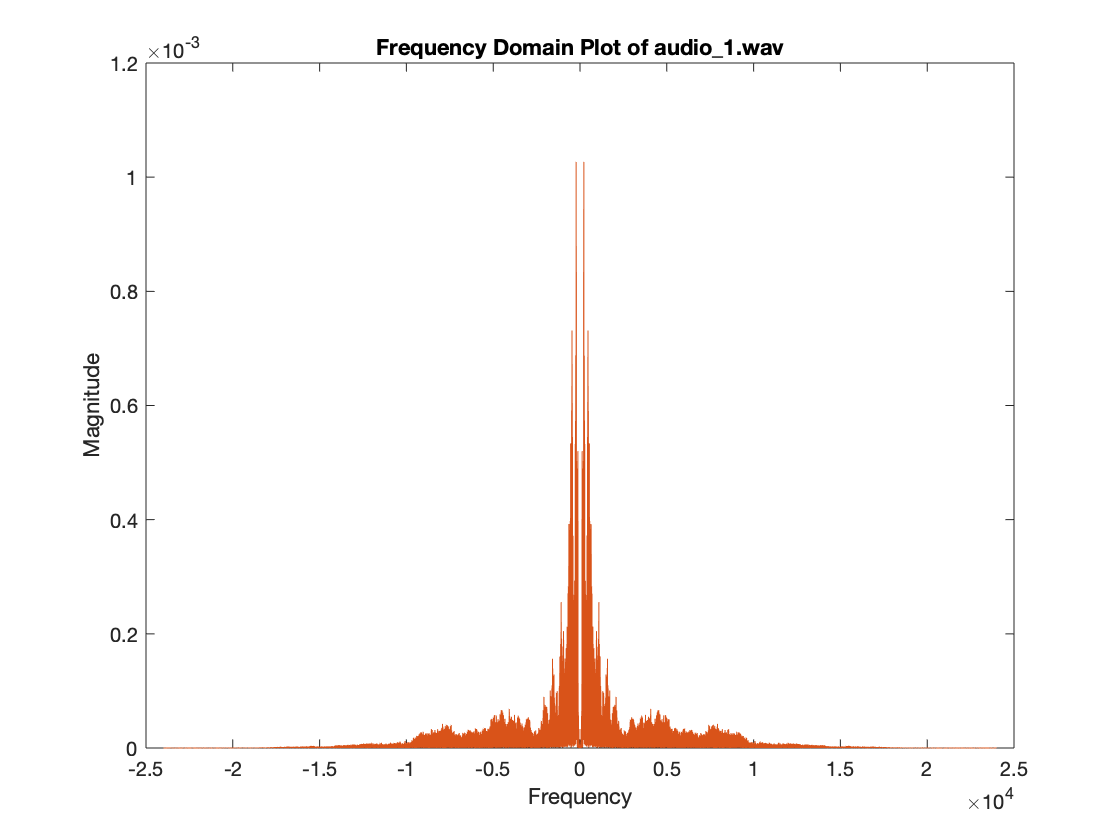

% frequency domain
% audio_1.wav
audio_length=length(audio_1);
df=rate_1/audio_length;
frequency_1=-rate_1/2:df:rate_1/2-df;
myaudio_fft_1=fftshift(fft(audio_1))/length(fft(audio_1));
plot(frequency_1,abs(myaudio_fft_1));
title('Frequency Domain Plot of audio\_1.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_1.png');

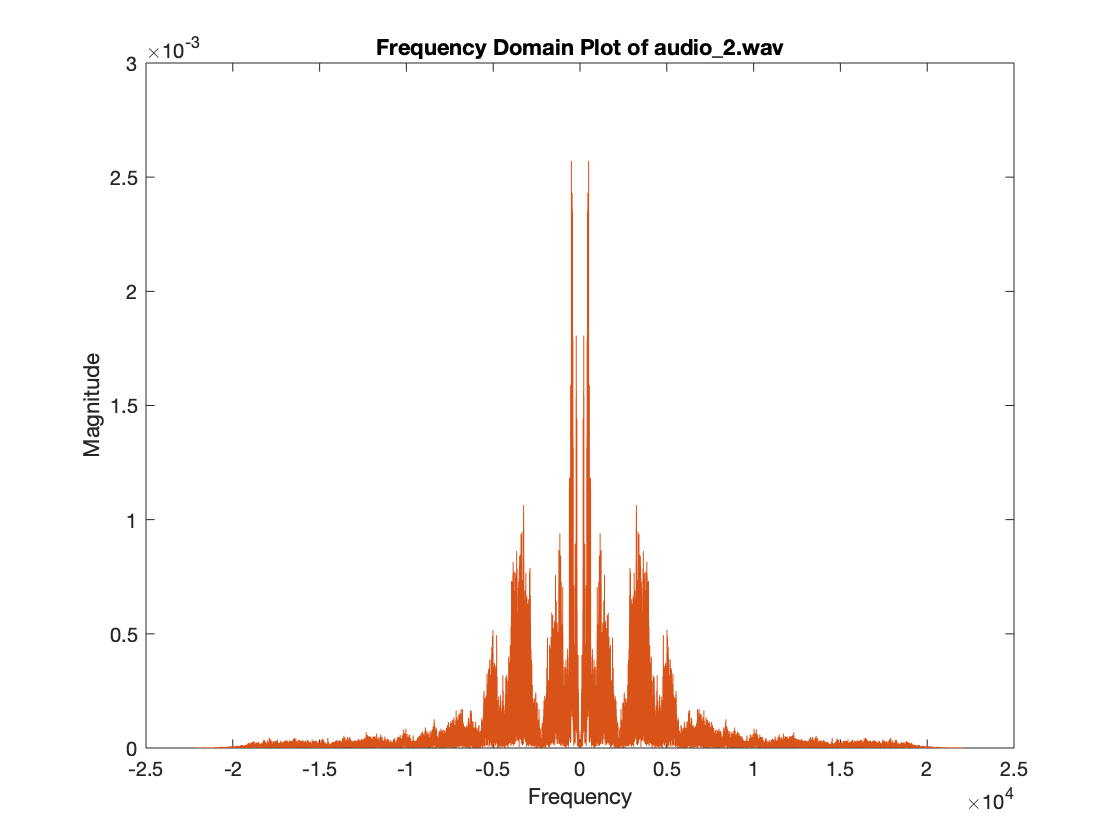

% audio_2.wav
audio_length=length(audio_2);
df=rate_2/audio_length;
frequency_2=-rate_2/2:df:rate_2/2-df;
myaudio_fft_2=fftshift(fft(audio_2))/length(fft(audio_2));
plot(frequency_2,abs(myaudio_fft_2));
title('Frequency Domain Plot of audio\_2.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_2.png');

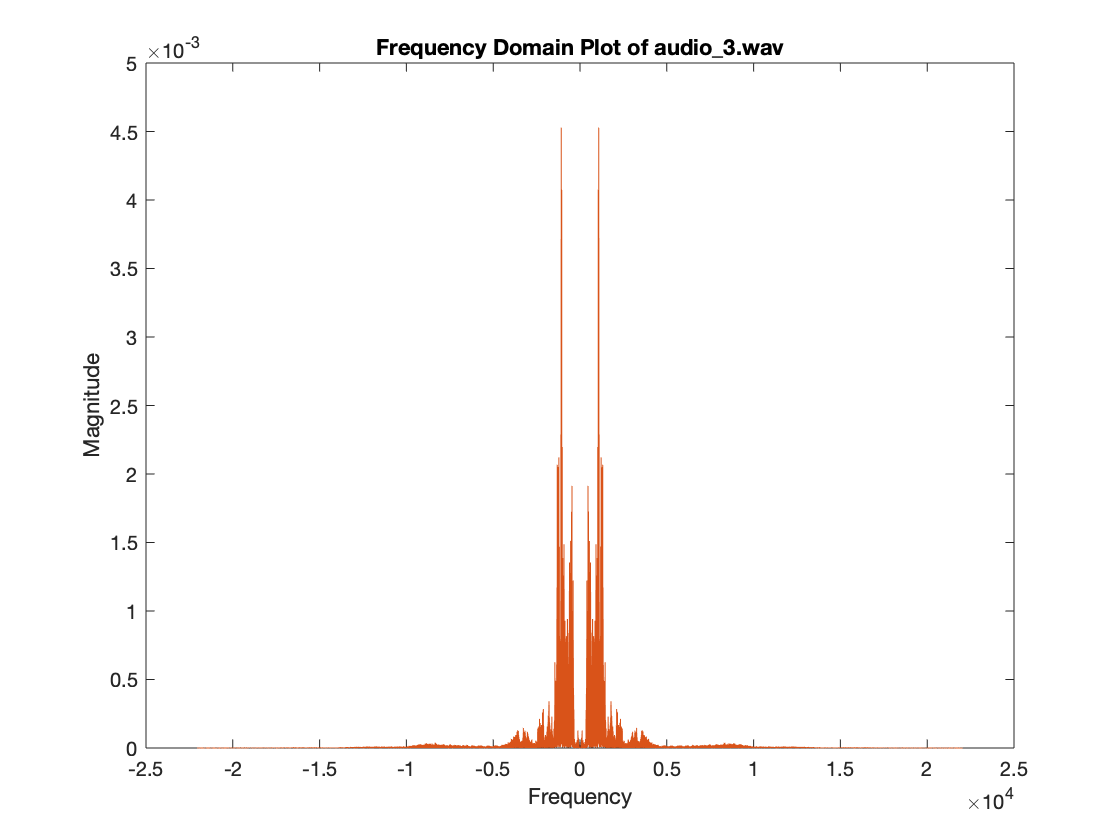

% audio_3.wav
audio_length=length(audio_3);
df=rate_3/audio_length;
frequency_3=-rate_3/2:df:rate_3/2-df;
myaudio_fft_3=fftshift(fft(audio_3))/length(fft(audio_3));
plot(frequency_3,abs(myaudio_fft_3));
title('Frequency Domain Plot of audio\_3.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_3.png');

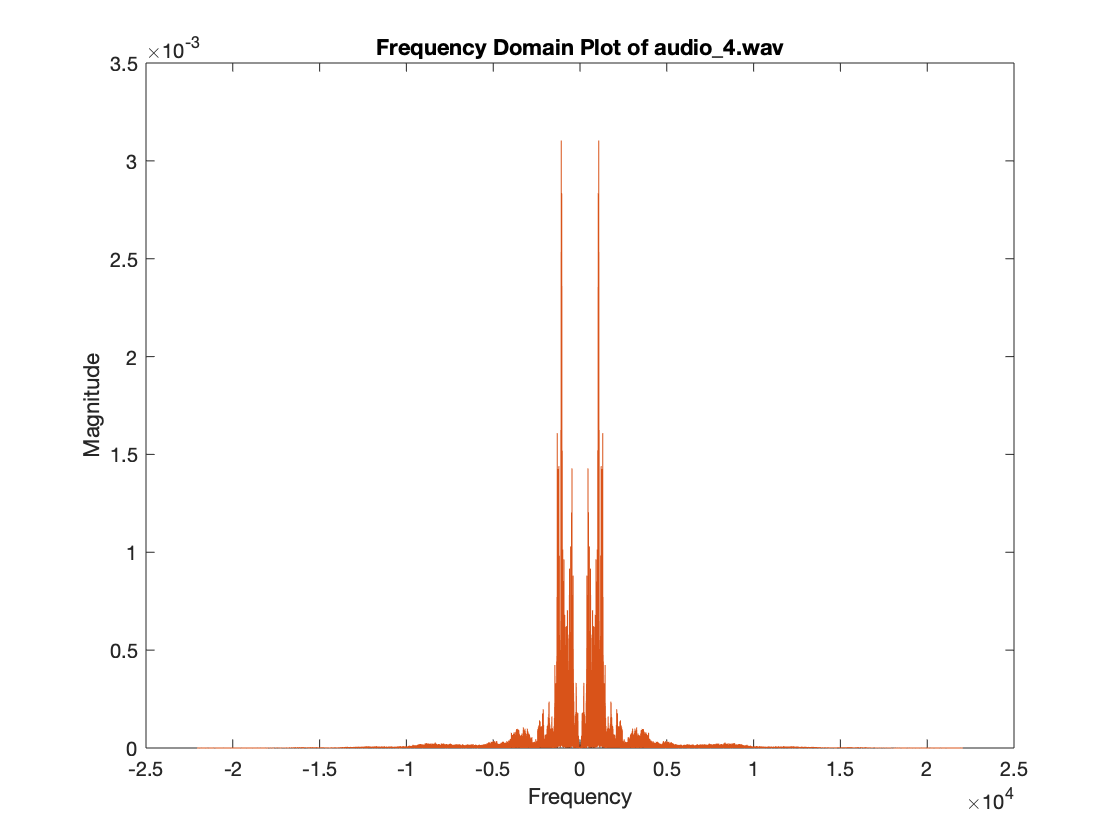

% audio_4.wav
audio_length=length(audio_4);
df=rate_4/audio_length;
frequency_4=-rate_4/2:df:rate_4/2-df;
myaudio_fft_4=fftshift(fft(audio_4))/length(fft(audio_4));
plot(frequency_4,abs(myaudio_fft_4));
title('Frequency Domain Plot of audio\_4.wav');
xlabel('Frequency');
ylabel('Magnitude');
saveas(gcf,'./result/frequency_domain/audio_4.png');

% Compare my audio with another girl
[sample_1,sample_rate_1]=audioread("./src/girl/speaking.wav");
[sample_2,sample_rate_2]=audioread("./src/girl/noise.wav");
[sample_3,sample_rate_3]=audioread("./src/girl/singing.wav");
[sample_4,sample_rate_4]=audioread("./src/girl/combination.wav");

% compare in frequency domain
% speaking signal
audio_length=length(sample_1);
df=sample_rate_1/audio_length;
sample_frequency=-sample_rate_1/2:df:sample_rate_1/2-df;
sample_audio_fft=fftshift(fft(sample_1))/length(fft(sample_1));
disp(frequency_1(1));

      -24000



disp(sample_frequency(1));

      -22050



disp(frequency_1(length(frequency_1)));

   2.4000e+04



disp(sample_frequency(length(sample_frequency)));

   2.2050e+04



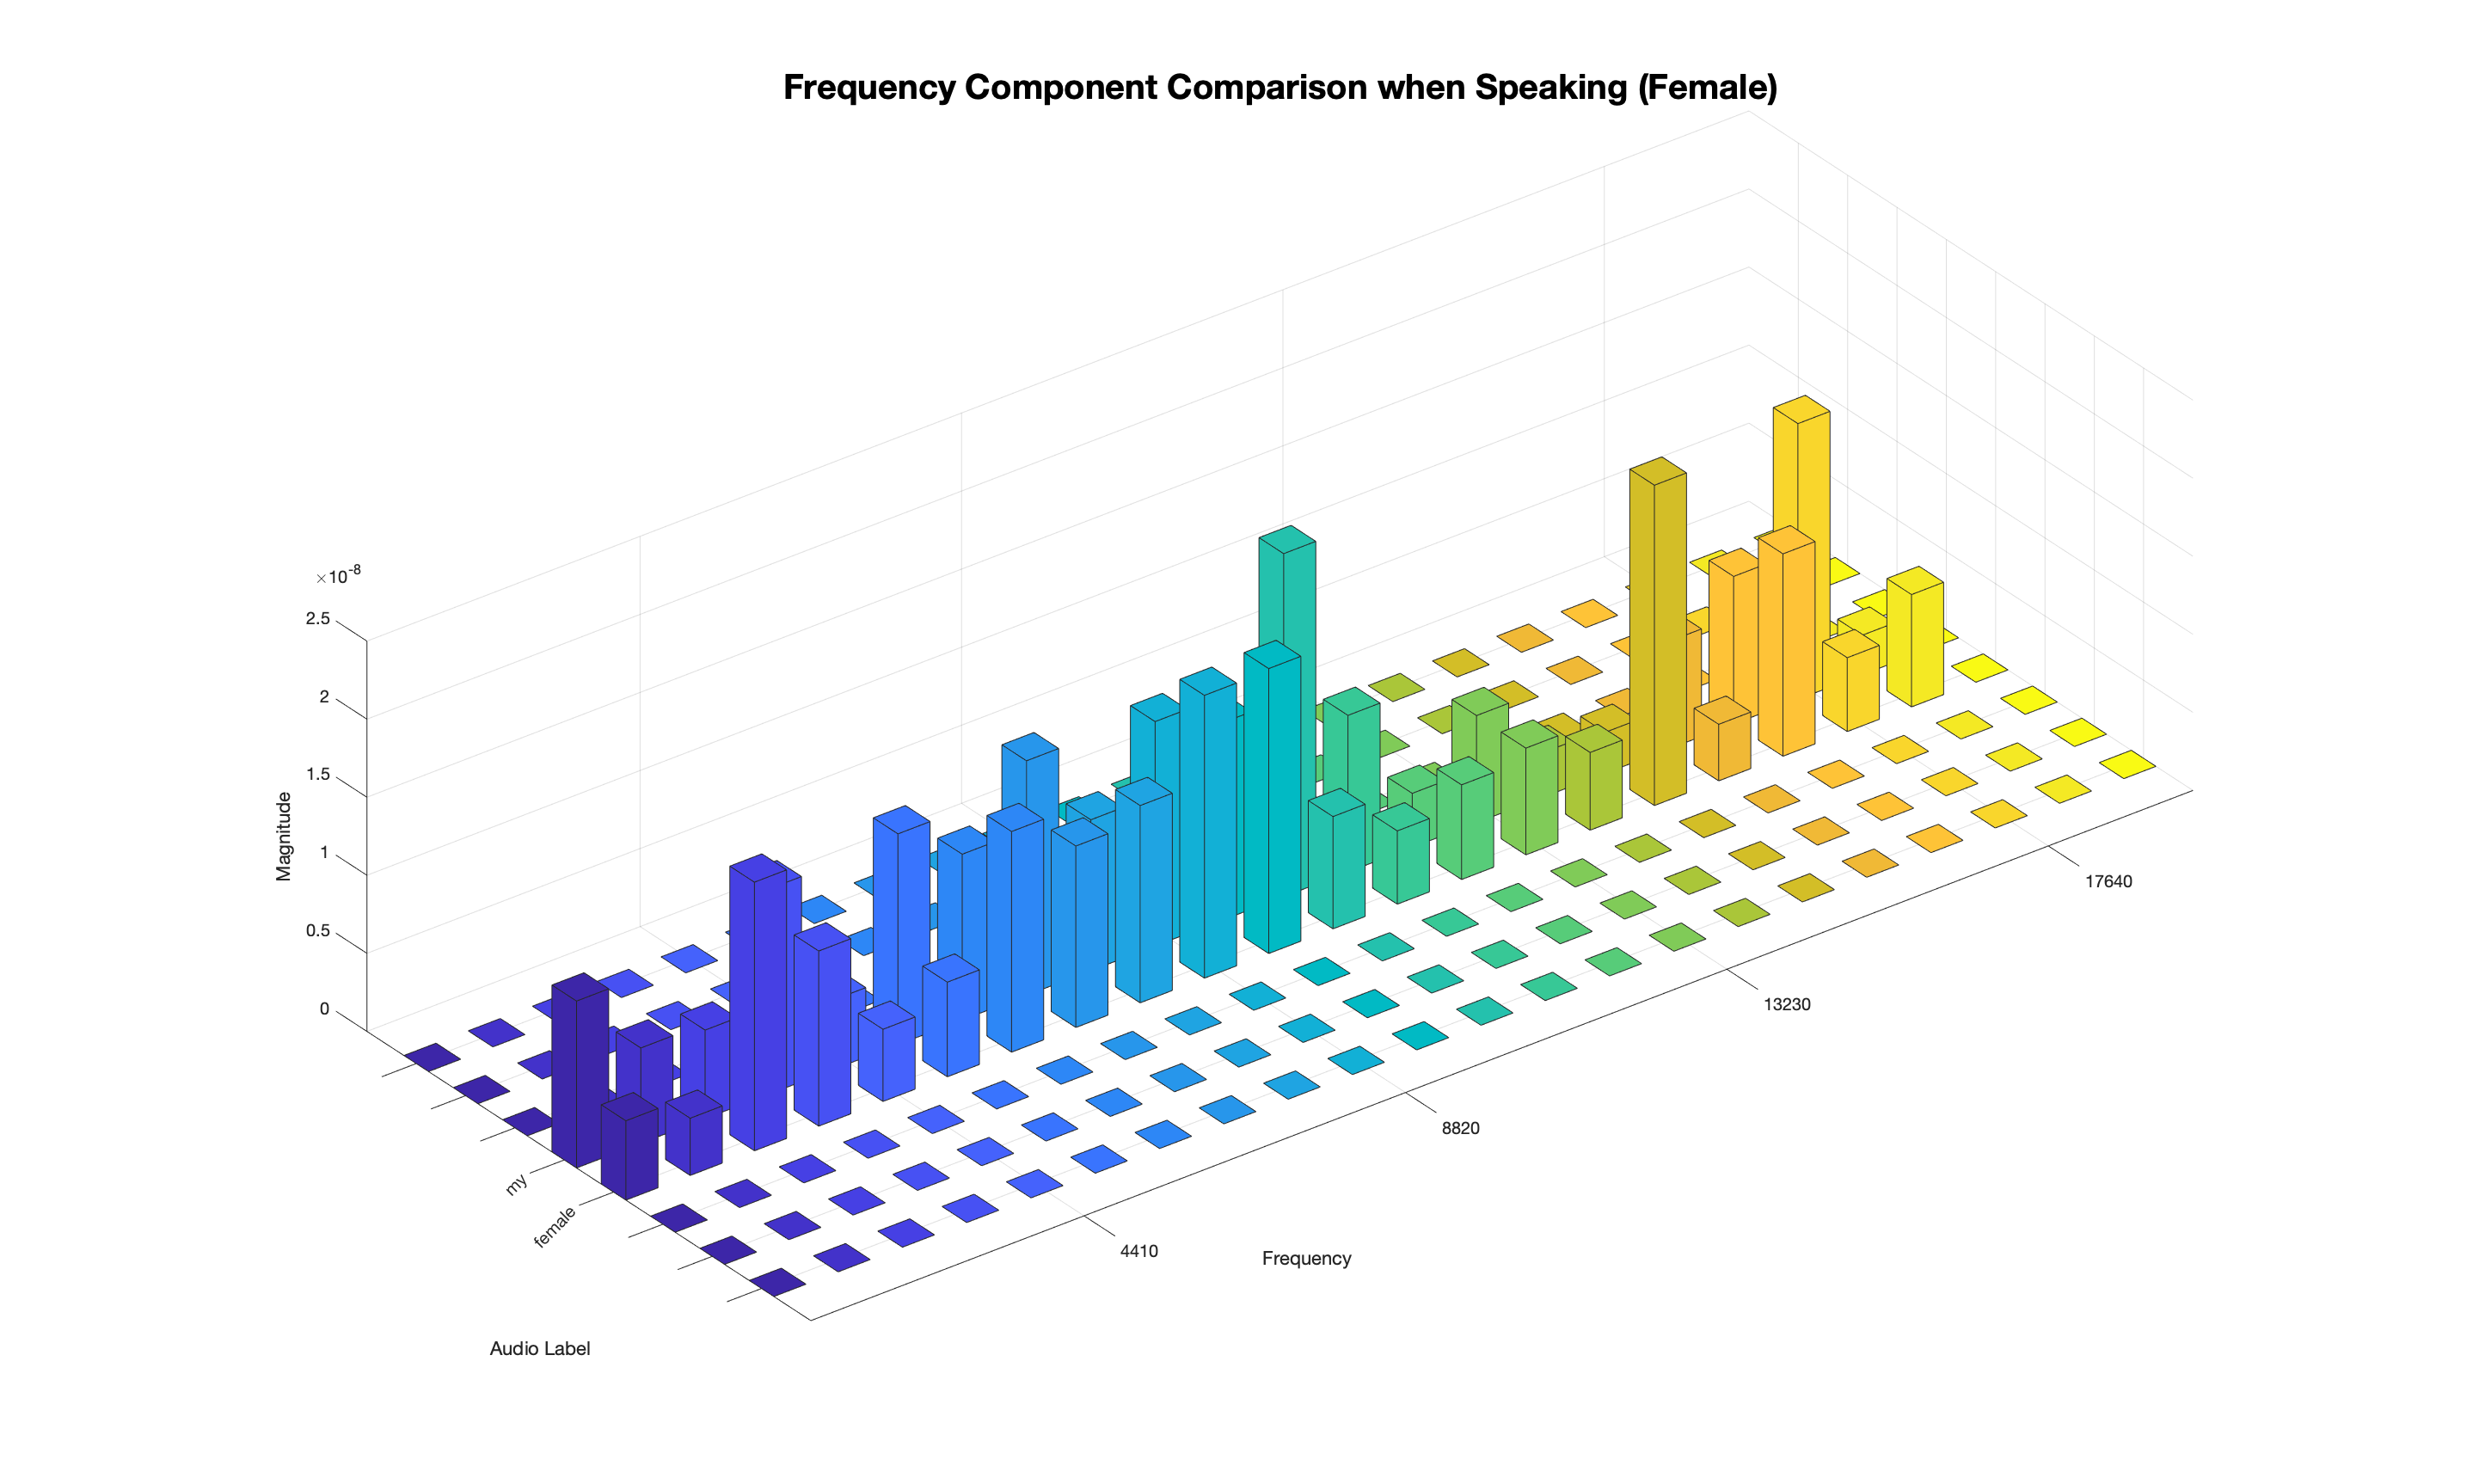

sample_points=0:1050:22050;
j=1;
my_magnitude=zeros(1,length(sample_points));
for i=1:length(frequency_1)
    if frequency_1(i)>=sample_points(j)
        my_magnitude(j)=abs(myaudio_fft_1(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end

j=1;
sample_magnitude=zeros(1,length(sample_points));
for i=1:length(sample_frequency)
    if sample_frequency(i)>=sample_points(j)
        sample_magnitude(j)=abs(sample_audio_fft(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end

dummies=zeros(1,length(sample_points));
x=[dummies;dummies;dummies;my_magnitude(1,:);sample_magnitude(1,:);dummies;dummies;dummies];
bar3(x,0.5);
xticklabels({4410,4410*2,4410*3,4410*4});
xlabel("Frequency");
ylabel("Audio Label");
zlabel("Magnitude");
yticklabels({"","","","my","female","","",""});
ytickangle(45);
title("Frequency Component Comparison when Speaking (Female)",'FontSize',20);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
saveas(gca,"./result/compare_with_girl/speaking.png");


% noise signal
audio_length=length(sample_2);
df=sample_rate_2/audio_length;
sample_frequency=-sample_rate_2/2:df:sample_rate_2/2-df;
sample_audio_fft=fftshift(fft(sample_2))/length(fft(sample_2));
disp(frequency_2(1));

      -22050



disp(sample_frequency(1));

      -22050



disp(frequency_2(length(frequency_2)));

   2.2050e+04



disp(sample_frequency(length(sample_frequency)));

   2.2050e+04



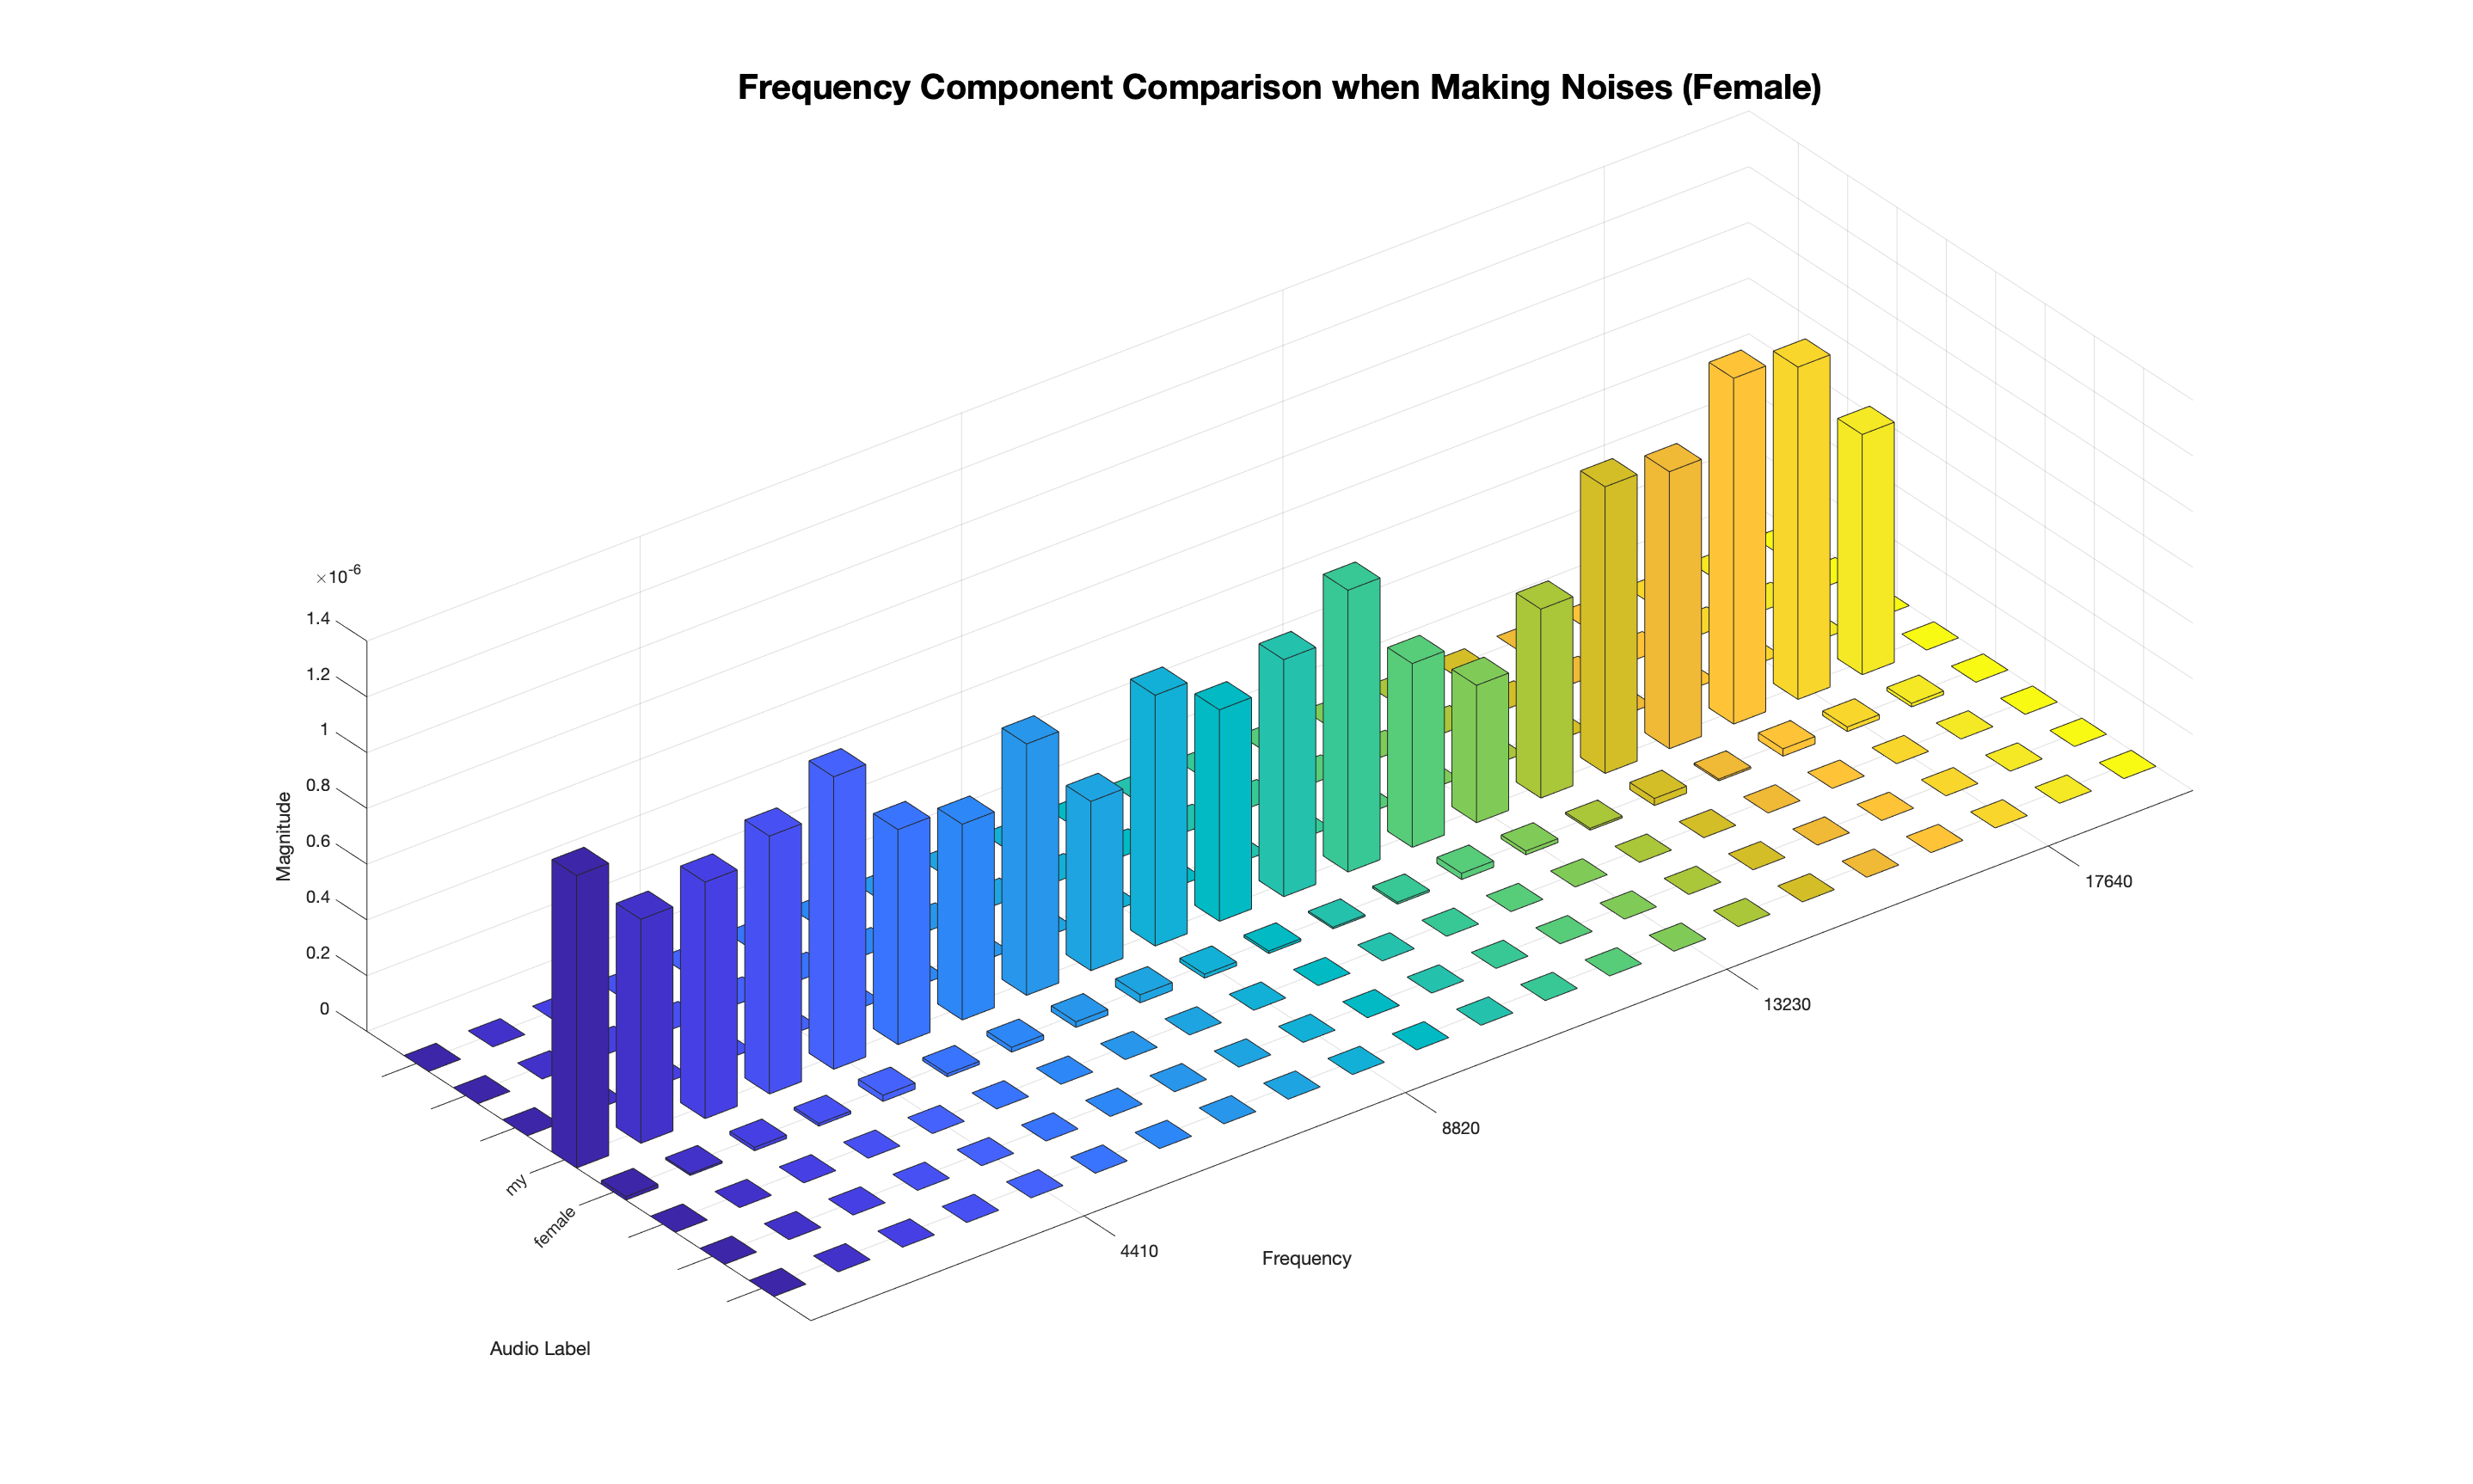

sample_points=0:1050:22050;
j=1;
my_magnitude=zeros(1,length(sample_points));
for i=1:length(frequency_2)
    if frequency_2(i)>=sample_points(j)
        my_magnitude(j)=abs(myaudio_fft_2(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end

j=1;
sample_magnitude=zeros(1,length(sample_points));
for i=1:length(sample_frequency)
    if sample_frequency(i)>=sample_points(j)
        sample_magnitude(j)=abs(sample_audio_fft(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end

dummies=zeros(1,length(sample_points));
x=[dummies;dummies;dummies;my_magnitude(1,:);sample_magnitude(1,:);dummies;dummies;dummies];
bar3(x,0.5);
xticklabels({4410,4410*2,4410*3,4410*4});
xlabel("Frequency");
ylabel("Audio Label");
zlabel("Magnitude");
yticklabels({"","","","my","female","","",""});
ytickangle(45);
title("Frequency Component Comparison when Making Noises (Female)",'FontSize',20);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
saveas(gca,"./result/compare_with_girl/noise.png");

% singing signal
audio_length=length(sample_3);
df=sample_rate_3/audio_length;
sample_frequency=-sample_rate_3/2:df:sample_rate_3/2-df;
sample_audio_fft=fftshift(fft(sample_3))/length(fft(sample_3));
disp(frequency_3(1));

      -22050



disp(sample_frequency(1));

      -22050



disp(frequency_3(length(frequency_2)));

  -1.8865e+04



disp(sample_frequency(length(sample_frequency)));

   2.2050e+04



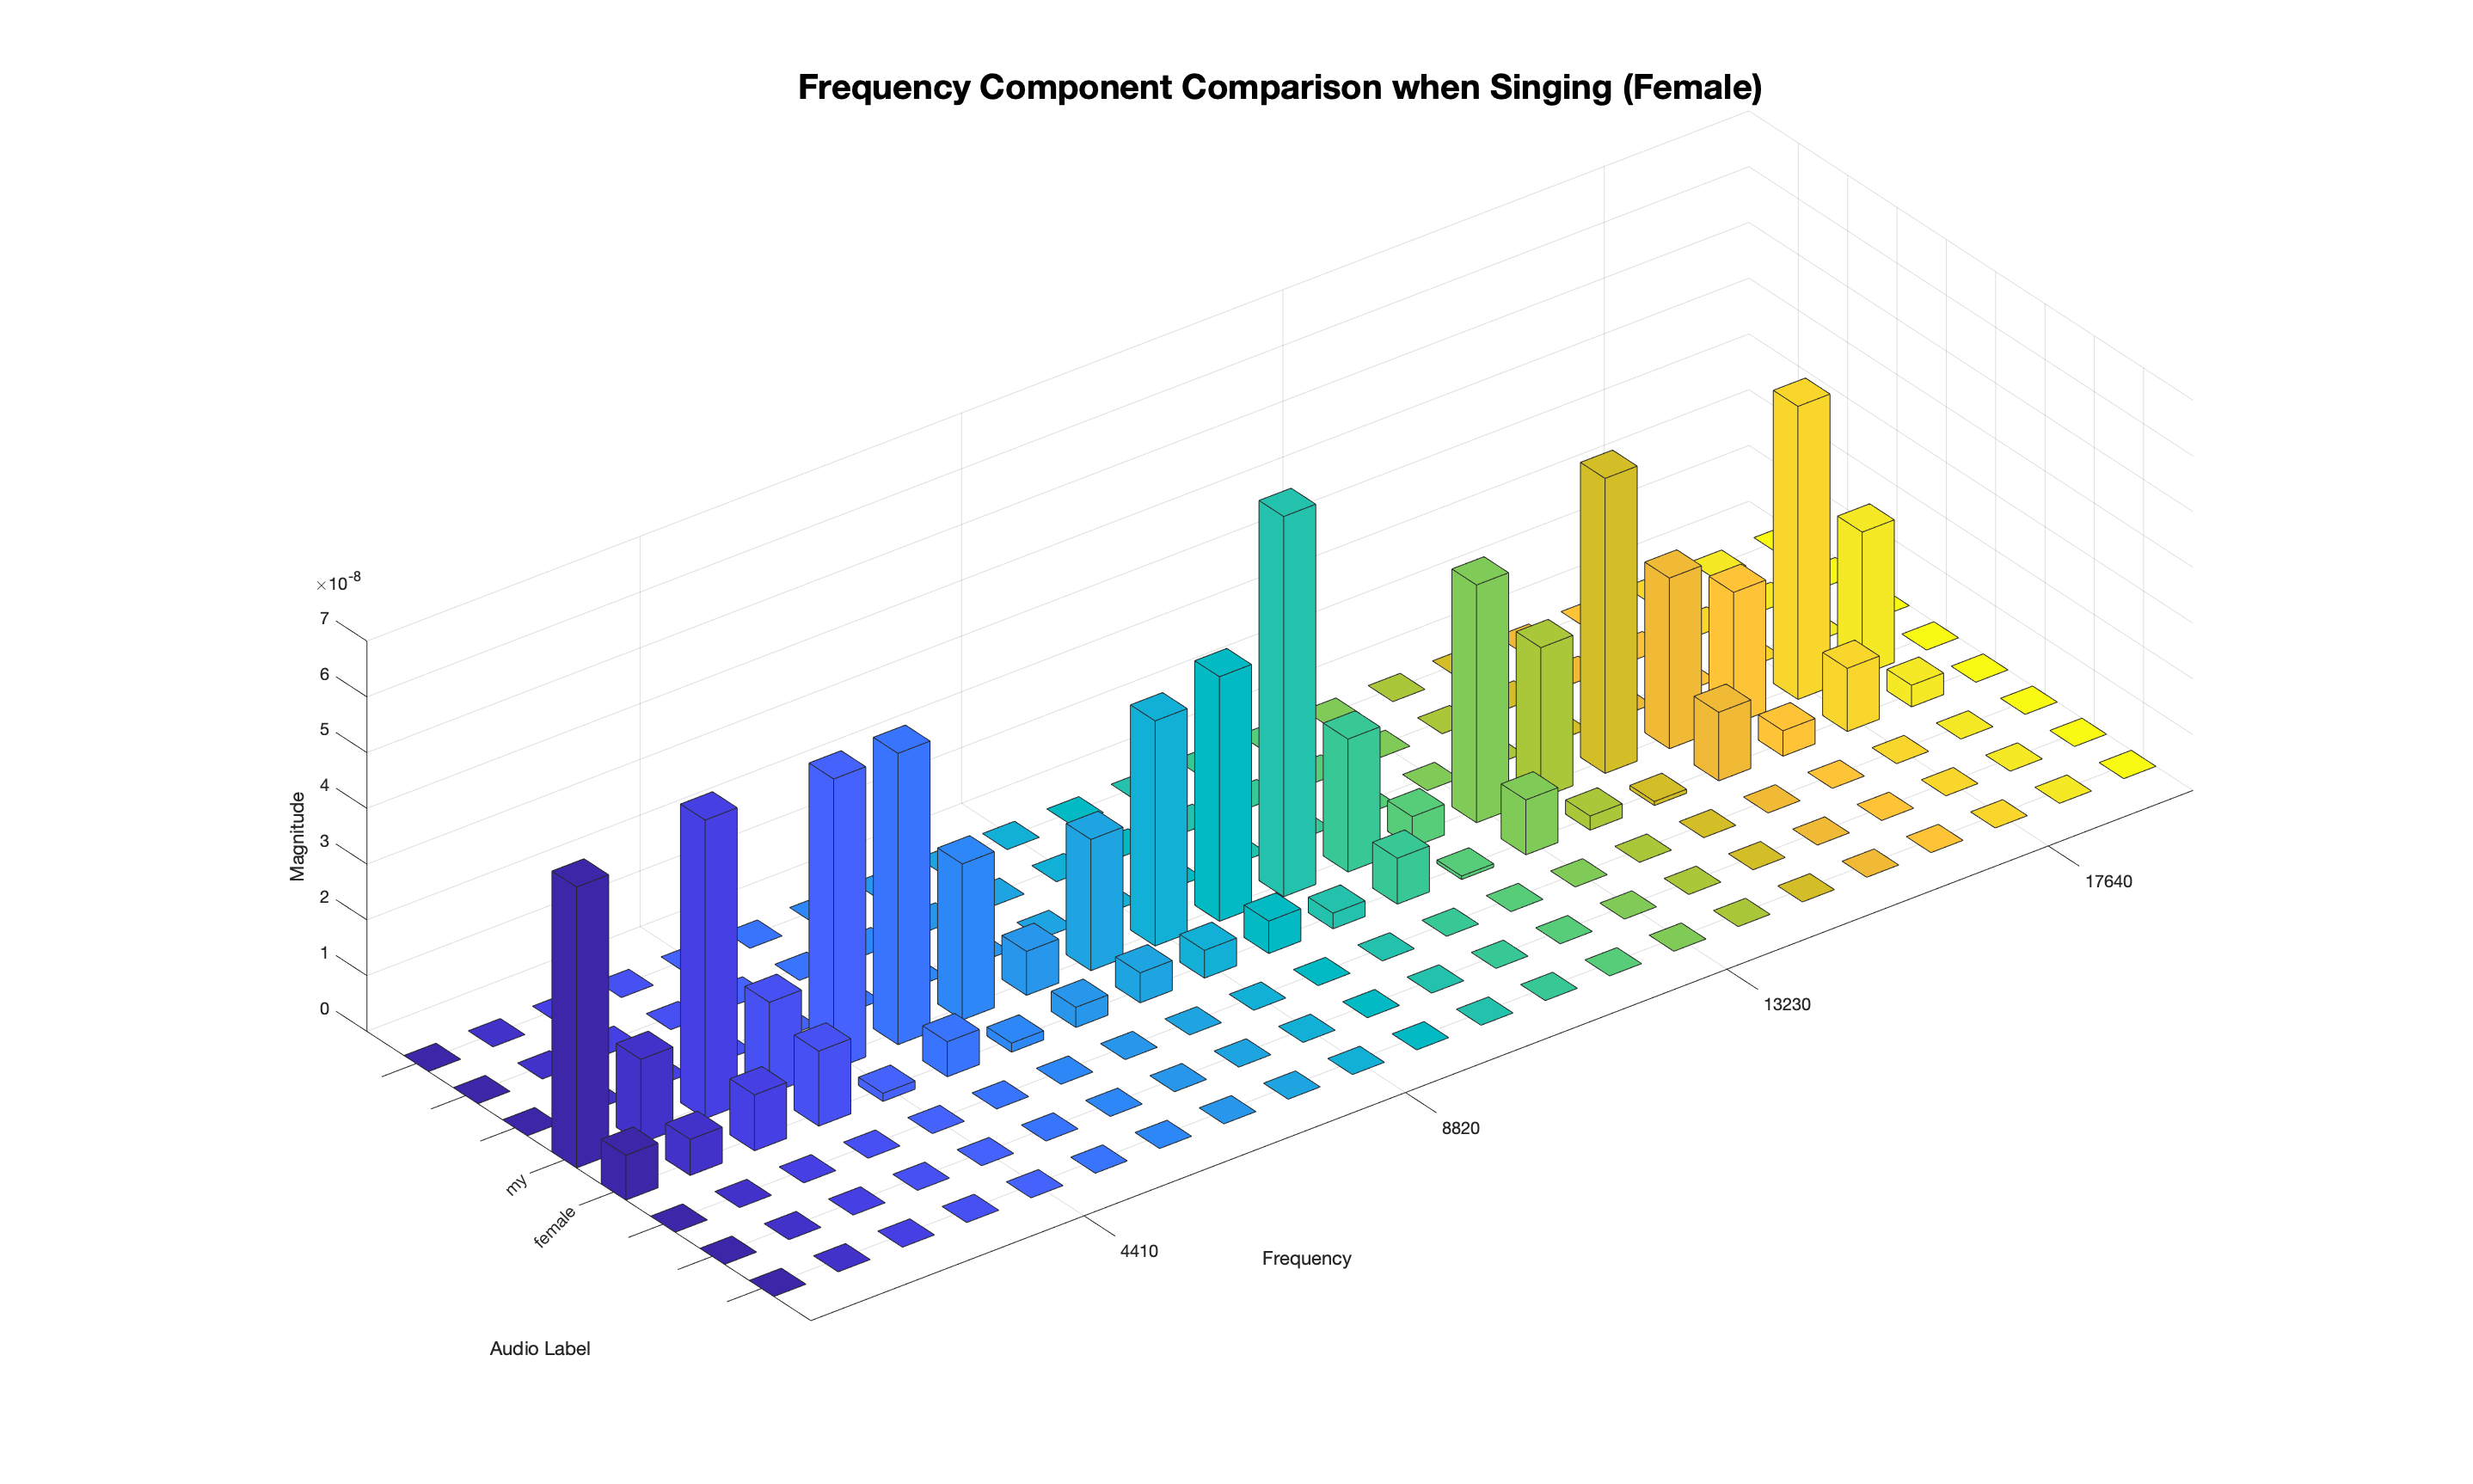

sample_points=0:1050:22050;
j=1;
my_magnitude=zeros(1,length(sample_points));
for i=1:length(frequency_3)
    if frequency_3(i)>=sample_points(j)
        my_magnitude(j)=abs(myaudio_fft_3(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end

j=1;
sample_magnitude=zeros(1,length(sample_points));
for i=1:length(sample_frequency)
    if sample_frequency(i)>=sample_points(j)
        sample_magnitude(j)=abs(sample_audio_fft(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end

dummies=zeros(1,length(sample_points));
x=[dummies;dummies;dummies;my_magnitude(1,:);sample_magnitude(1,:);dummies;dummies;dummies];
bar3(x,0.5);
xticklabels({4410,4410*2,4410*3,4410*4});
xlabel("Frequency");
ylabel("Audio Label");
zlabel("Magnitude");
yticklabels({"","","","my","female","","",""});
ytickangle(45);
title("Frequency Component Comparison when Singing (Female)",'FontSize',20);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
saveas(gca,"./result/compare_with_girl/singing.png");

% combination signal
audio_length=length(sample_4);
df=sample_rate_4/audio_length;
sample_frequency=-sample_rate_4/2:df:sample_rate_4/2-df;
sample_audio_fft=fftshift(fft(sample_4))/length(fft(sample_4));
disp(frequency_4(1));

      -22050



disp(sample_frequency(1));

      -22050



disp(frequency_4(length(frequency_4)));

   2.2050e+04



disp(sample_frequency(length(sample_frequency)));

   2.2050e+04



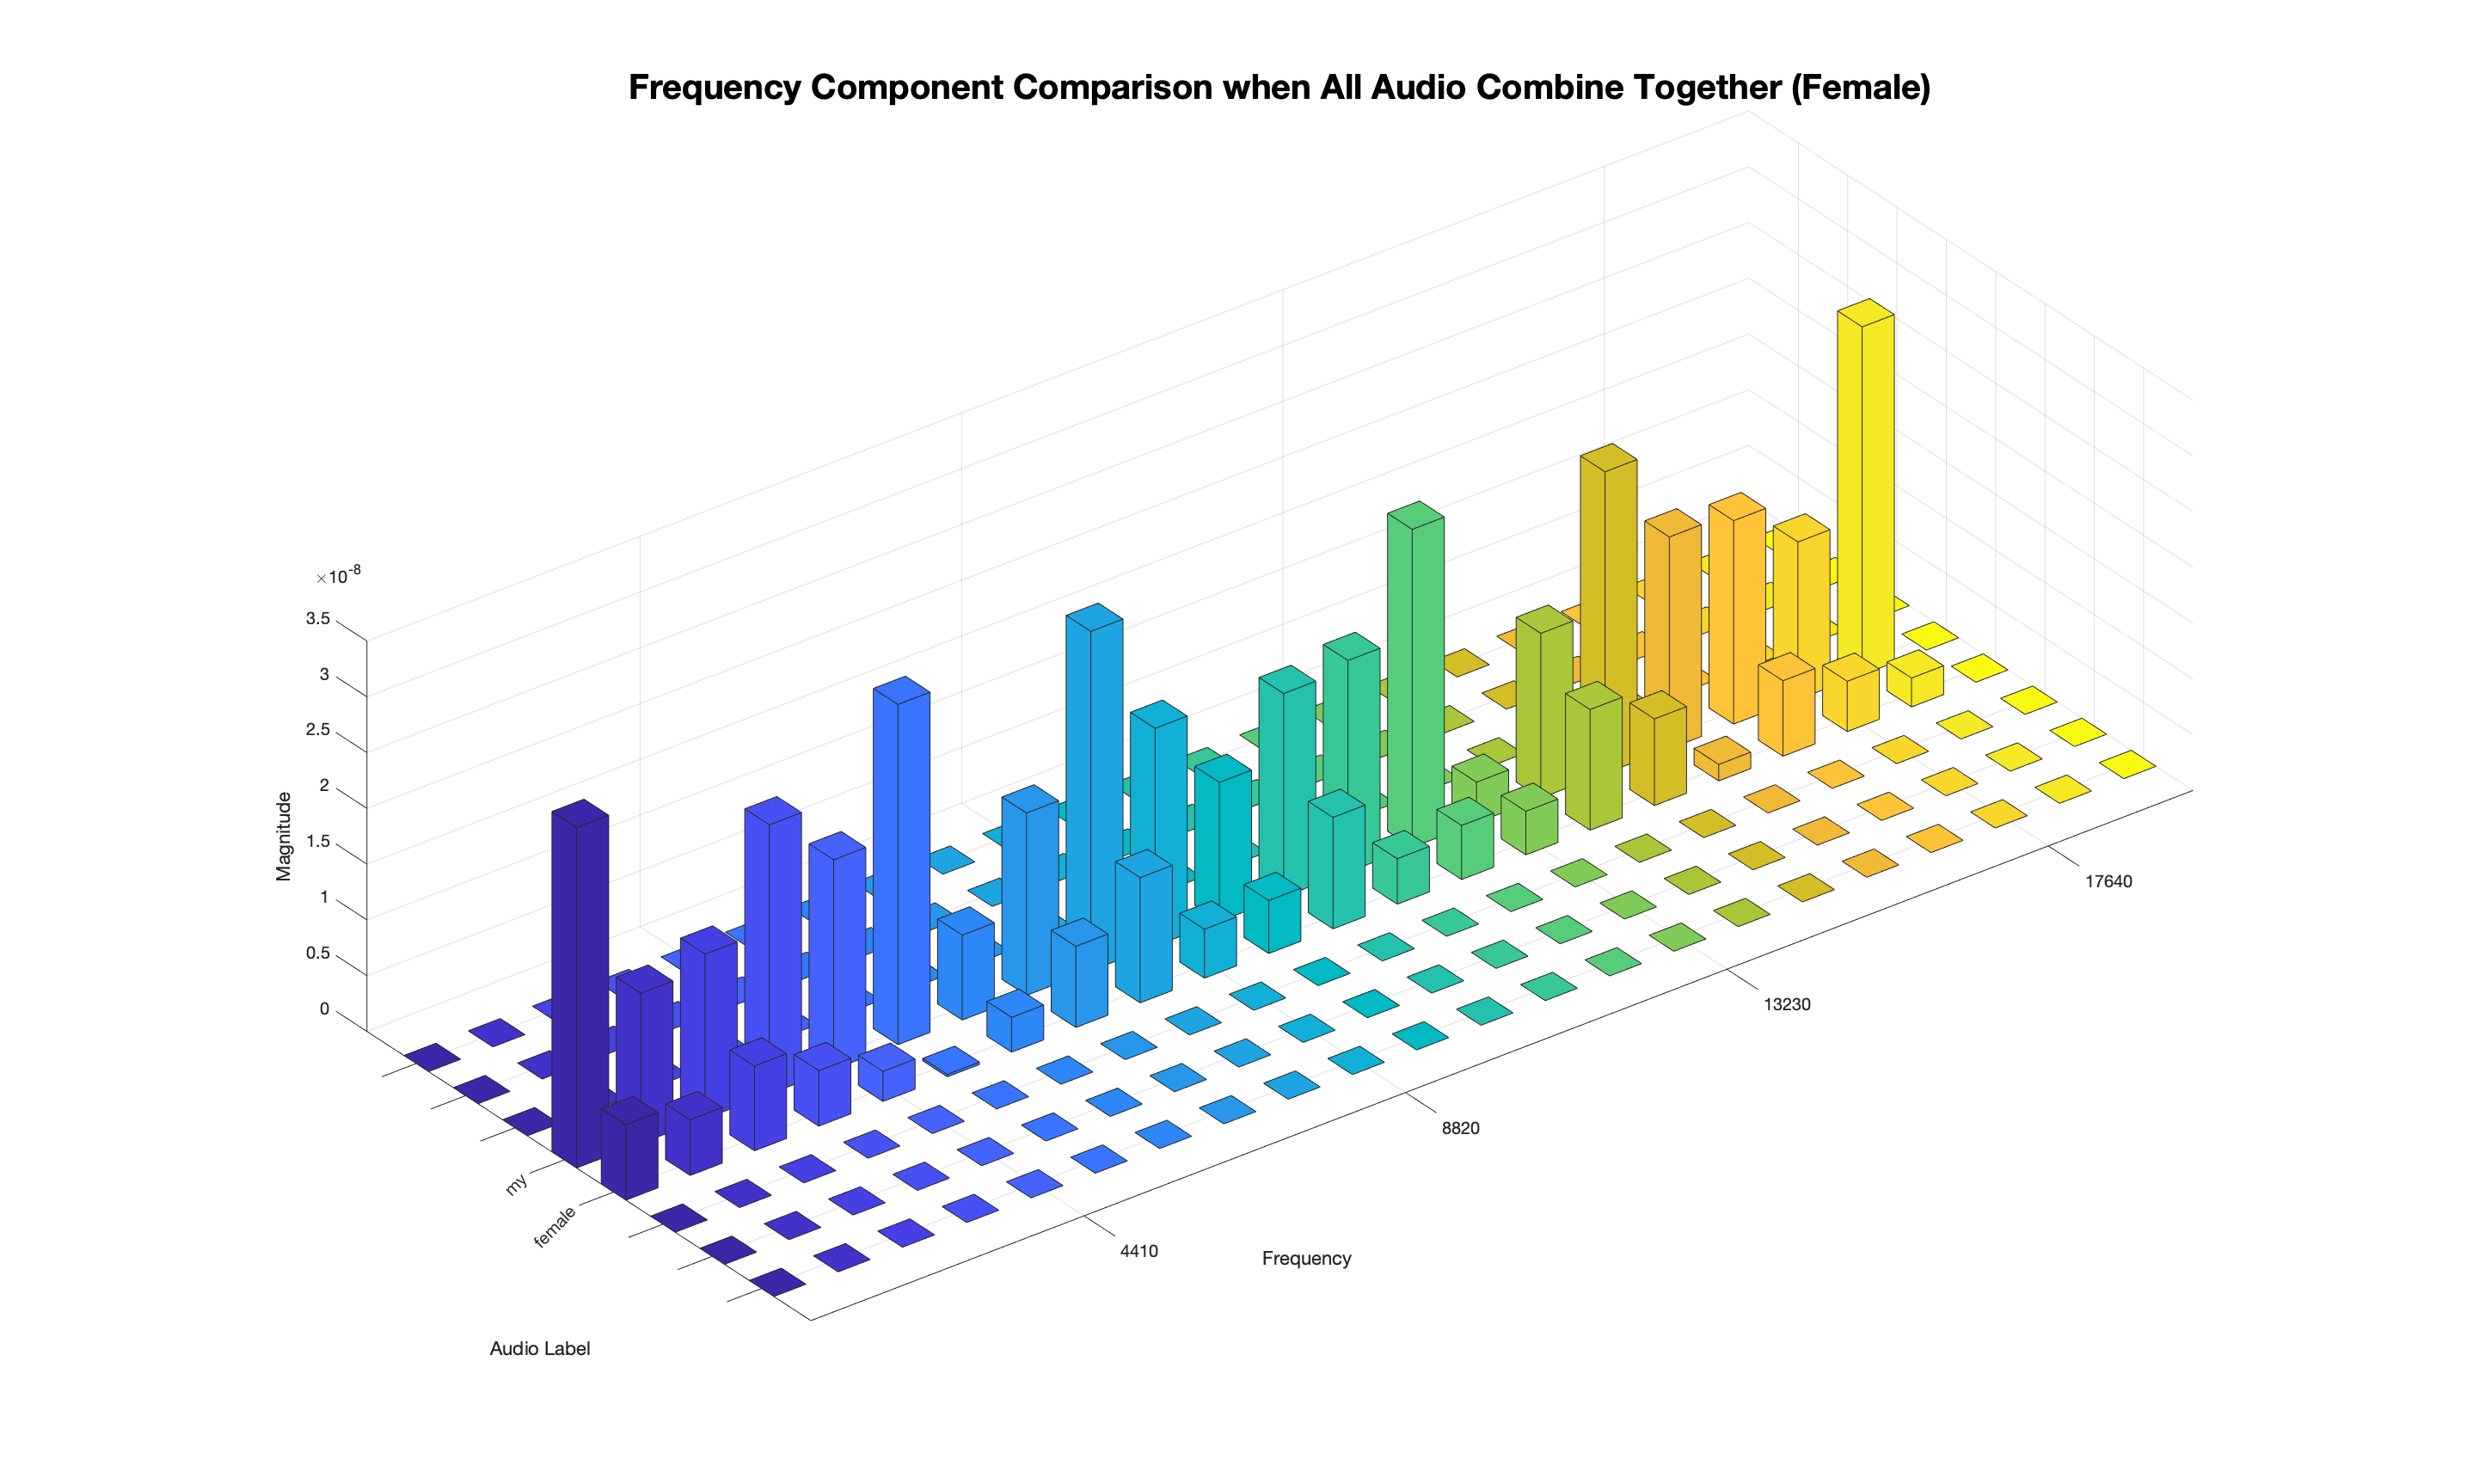

sample_points=0:1050:22050;
j=1;
my_magnitude=zeros(1,length(sample_points));
for i=1:length(frequency_4)
    if frequency_4(i)>=sample_points(j)
        my_magnitude(j)=abs(myaudio_fft_4(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end

j=1;
sample_magnitude=zeros(1,length(sample_points));
for i=1:length(sample_frequency)
    if sample_frequency(i)>=sample_points(j)
        sample_magnitude(j)=abs(sample_audio_fft(j,1));
        j=j+1;
    end
    if j==length(sample_points)
        break;
    end
end
dummies=zeros(1,length(sample_points));
x=[dummies;dummies;dummies;my_magnitude(1,:);sample_magnitude(1,:);dummies;dummies;dummies];
bar3(x,0.5);
xticklabels({4410,4410*2,4410*3,4410*4});
xlabel("Frequency");
ylabel("Audio Label");
zlabel("Magnitude");
yticklabels({"","","","my","female","","",""});
ytickangle(45);
title("Frequency Component Comparison when All Audio Combine Together (Female)",'FontSize',20);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
saveas(gcf,"./result/compare_with_girl/combination.png");

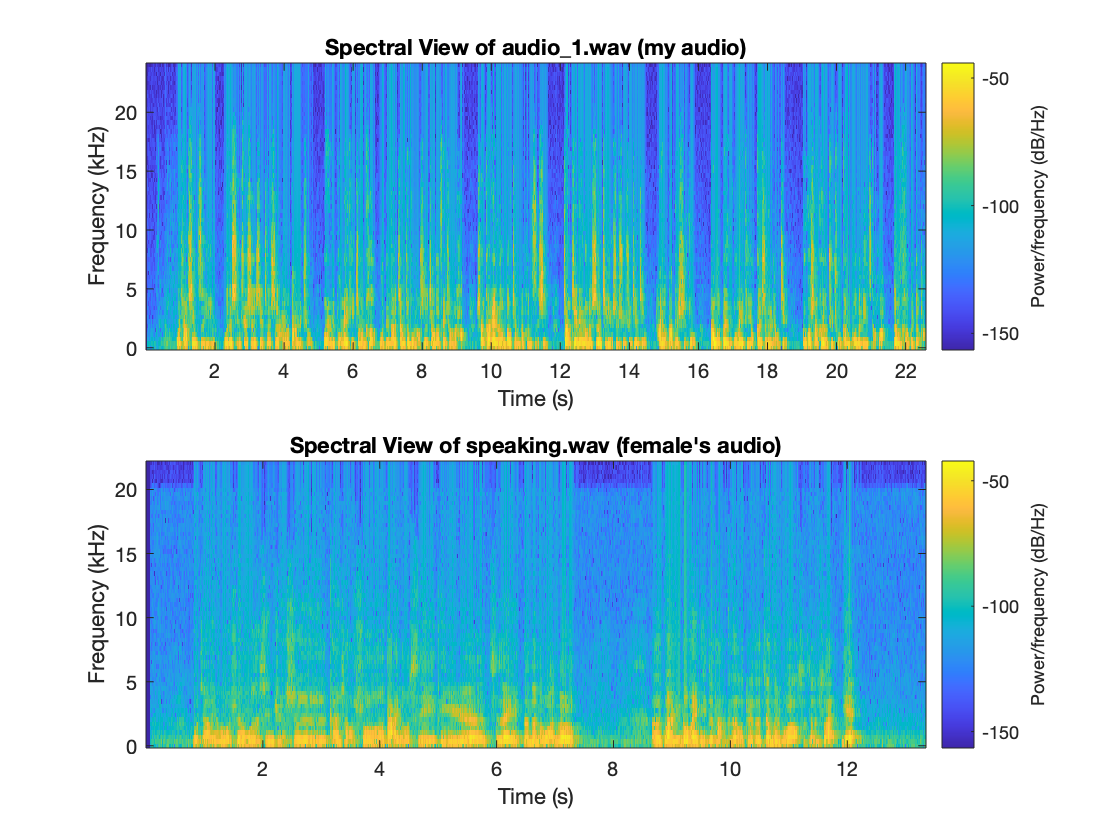

% Compare in spectral view
% Speaking signal
subplot(2,1,1);
audio_vec=audio_1(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,rate_1,'yaxis');
title("Spectral View of audio\_1.wav (my audio)");
subplot(2,1,2);
audio_vec=sample_1(:,1);
win=128;
hop=win/2;
nfft=win;
spectrogram(audio_vec,win,hop,nfft,sample_rate_1,'yaxis');
title("Spectral View of speaking.wav (female's audio)");
saveas(gcf,"./result/compare_with_girl/spectral_speaking.png");